## **Task1:**

### Define System Parameters

According to the schematic of the admittance matrix in the courseware, it can be formulated as follows:

$Y_{\textrm{ii}} =\frac{1}{Z_{\textrm{Loadi}} }+\sum_k^n \frac{1}{{\textrm{ZL}}_{\textrm{ik}} }$; $Y_{\textrm{ik}} =-\frac{1}{Z_{\textrm{Lik}} }$

%% Problem 1
% Good habit: Clear the workspace and command window
clear;
clc;

% Given parameters
V0 = 1.02; % Voltage at Node 0 (Slack Node Voltage) [pu]
ZL01 = 0.01; % Impedance between Node 0 and Node 1 [pu]
ZL12 = 0.03 + 1i*0.01; % Impedance between Node 1 and Node 2 [pu]
ZL23 = 0.05 + 1i*0.01; % Impedance between Node 2 and Node 3 [pu]

YLoad1 = 0.1 - 1i*0.03; % Load admittance at Node 1 [pu]
SGEN2 = 0.01; % Power generation at Node 2 [pu]
SLOAD3 = 0.8 - 1i*0.01; % Load power at Node 3 [pu]

% Admittance calculations
YL01 = 1 / ZL01; % Admittance between Node 0 and Node 1
YL12 = 1 / ZL12; % Admittance between Node 1 and Node 2
YL23 = 1 / ZL23; % Admittance between Node 2 and Node 3

% Extract the load power components at Node 3
Pload3 = real(SLOAD3); % Active power component
Qload3 = imag(SLOAD3); % Reactive power component

### Construct the Admittance Matrix

The admittance matrix  $Y$  (or bus admittance matrix) is constructed based on the network configuration. For a three-node network, the admittance matrix  Y  is a 3x3 matrix with elements defined as follows:

#### Diagonal Elements:

$Y_{\textrm{ii}}$ =  sum of all admittances connected to node  i .

#### Off-Diagonal Elements:

$Y_{\textrm{ik}}$ = $-$admittance between nodes  i  and  k , if a direct connection exists between them.

So, we calculate:

% Node Admittance Matrix (Y matrix)
Y = [YL01, -YL01, 0, 0;
    -YL01, YL01 + YL12 + YLoad1, -YL12, 0;
    0, -YL12, YL12 + YL23, -YL23;
    0, 0, -YL23, YL23];

% Extract the conductance (G) and susceptance (B) from the admittance matrix
G = real(Y); % Conductance matrix
B = imag(Y); % Susceptance matrix

### Step 3: Define Power Flow Equations

According to the slide

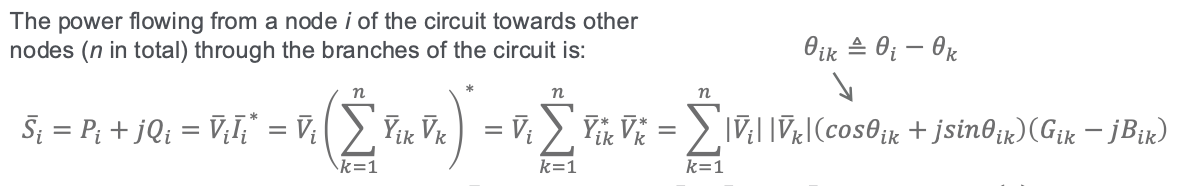

For each PQ node, we define active power $P$ and reactive power $Q$ balance equations. Using $S_i =P_i +{\textrm{jQ}}_i =V_i {I_i }^*$

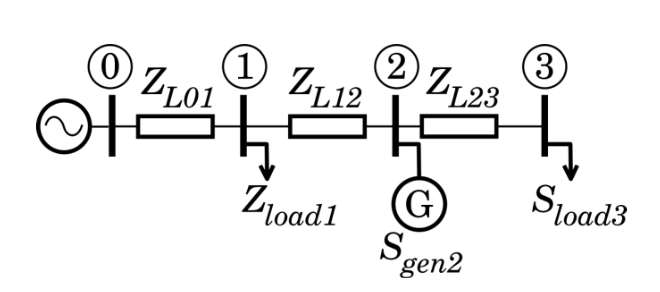

Using the admittance matrix, we expand each $P$ and $Q$ equations as follows:

#### 1. Node 1(PQ Node)


$$\begin{array}{l}
P_1 =|V_1 ||V_0 |\left(G_{10} \cos \left(\theta_1 -0\right)+B_{10} \sin \left(\theta_1 -0\right)\right)+|V_1 |^2 G_{11} \\
Q_1 =|V_1 ||V_0 |\left(G_{10} \sin \left(\theta_1 -\theta_2 \right)-B_{10} \cos \left(\theta_1 -\theta_0 \right)\right)-|V_1 |^2 B_{11} 
\end{array}$$


#### 2. Node 2(PQ Node with Generation)


$$\begin{array}{l}
P_2 =|V_2 ||V_1 |\left(G_{12} \cos \left(\theta_2 -\theta_1 \right)+B_{12} \sin \left(\theta_2 -\theta_1 \right)\right)+|V_2 |^2 G_{22} -{\textrm{Real}\left(S_{\textrm{GEN2}} \right)} \\
Q_2 =|V_2 ||V_1 |\left(G_{12} \sin \left(\theta_2 -\theta_1 \right)-B_{12} \cos \left(\theta_2 -\theta_1 \right)\right)-|V_2 |^2 B_{22} -\textrm{Imag}\left(S_{\textrm{GEN2}} \right)
\end{array}$$


#### 3. Node 3(PQ Node with Load)


$$\begin{array}{l}
P_3 =|V_3 ||V_2 |\left(G_{23} \cos \left(\theta_3 -\theta_2 \right)+B_{23} \sin \left(\theta_3 -\theta_2 \right)\right)+|V_3 |^2 G_{33} +P_{\textrm{LOAD3}} \\
Q_3 =|V_3 ||V_2 |\left(G_{23} \sin \left(\theta_3 -\theta_2 \right)-B_{23} \cos \left(\theta_3 -\theta_2 \right)\right)-|V_3 |^2 B_{33} +Q_{\textrm{LOAD3}} 
\end{array}$$


%% Define Power Balance Equations
% Power balance equations
f = @(V1, V2, V3, theta1, theta2, theta3) [
    % Active power balance at Node 1
    V0 * V1 * (G(1,2) * cos(theta1) + B(1,2) * sin(theta1)) + ...
    V1^2 * G(2,2) + V1 * V2 * (G(2,3) * cos(theta1 - theta2) + B(2,3) * sin(theta1 - theta2));

    % Active power balance at Node 2
    V1 * V2 * (G(2,3) * cos(theta2 - theta1) + B(2,3) * sin(theta2 - theta1)) + ...
    V2^2 * G(3,3) + V2 * V3 * (G(3,4) * cos(theta2 - theta3) + B(3,4) * sin(theta2 - theta3)) - real(SGEN2);

    % Active power balance at Node 3
    V2 * V3 * (G(3,4) * cos(theta3 - theta2) + B(3,4) * sin(theta3 - theta2)) + ...
    V3^2 * G(4,4) + Pload3;

    % Reactive power balance at Node 1
    V0 * V1 * (G(1,2) * sin(theta1) - B(1,2) * cos(theta1)) - ...
    V1^2 * B(2,2) + V1 * V2 * (G(2,3) * sin(theta1 - theta2) - B(2,3) * cos(theta1 - theta2));

    % Reactive power balance at Node 2
    V1 * V2 * (G(2,3) * sin(theta2 - theta1) - B(2,3) * cos(theta2 - theta1)) - ...
    V2^2 * B(3,3) + V2 * V3 * (G(3,4) * sin(theta2 - theta3) - B(3,4) * cos(theta2 - theta3));

    % Reactive power balance at Node 3
    V2 * V3 * (G(3,4) * sin(theta3 - theta2) - B(3,4) * cos(theta3 - theta2)) - ...
    V3^2 * B(4,4) + Qload3;
];

% Convert the equations into a single-variable function for solving
fp = @(x) f(x(1), x(2), x(3), x(4), x(5), x(6));

### Set up Initial Guess for Voltage and Angles/ Use *Newton-Raphson* Iterative Solution

- 
$$|V_1 |=1\ldotp 0p\ldotp u\ldotp ,|V_2 |=1\ldotp 0p\ldotp u\ldotp ,|V_3 |=1\ldotp 0p\ldotp u\ldotp$$


- 
$$\theta_1 =0,\theta_2 =0,\theta_3 =0\;$$


%% Solve Using fsolve
[x, fval, info] = fsolve(fp, [1.0;1.0;1.0;0;0;0]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


#### Review the Results

Using the code, we calculated the voltage magnitudes for nodes  $V_1$  and  $V_2$  and can analyze whether they fall within the range. If we assume:

Node 1 Voltage  $V_1$  and Node 2 Voltage  $V_2$  should both fall within 0.96 pu to 1.04 pu if that is a stable situation.

% Extract computation results
V1 = x(1); % Voltage magnitude at Node 1
V2 = x(2); % Voltage magnitude at Node 2
V3 = x(3); % Voltage magnitude at Node 3
theta1 = x(4); % Voltage angle at Node 1
theta2 = x(5); % Voltage angle at Node 2
theta3 = x(6); % Voltage angle at Node 3

%% Display Results
fprintf('Node Voltages:\n');

Node Voltages:


fprintf('V0 = %.4f pu (Slack Node)\n', V0);

V0 = 1.0200 pu (Slack Node)


fprintf('V1 = %.4f pu, θ1 = %.4f rad\n', V1, theta1);

V1 = 1.0106 pu, θ1 = 0.0003 rad


fprintf('V2 = %.4f pu, θ2 = %.4f rad\n', V2, theta2);

V2 = 0.9855 pu, θ2 = -0.0080 rad


fprintf('V3 = %.4f pu, θ3 = %.4f rad\n', V3, theta3);

V3 = 0.9431 pu, θ3 = -0.0172 rad



% Extract results
V1_complex = V1 * exp(1i * theta1); % Complex voltage at Node 1
V2_complex = V2 * exp(1i * theta2); % Complex voltage at Node 2
V3_complex = V3 * exp(1i * theta3); % Complex voltage at Node 3

%% Calculate Line Currents
I01 = (V1_complex - V0) * YL01; % Current from Node 0 to Node 1
I12 = (V2_complex - V1_complex) * YL12; % Current from Node 1 to Node 2
I23 = (V3_complex - V2_complex) * YL23; % Current from Node 2 to Node 3
fprintf('\nLine Currents:\n');


Line Currents:


fprintf('I01 = %.4f + j%.4f pu\n', real(I01), imag(I01));

I01 = -0.9392 + j0.0342 pu


fprintf('I12 = %.4f + j%.4f pu\n', real(I12), imag(I12));

I12 = -0.8382 + j0.0039 pu


fprintf('I23 = %.4f + j%.4f pu\n', real(I23), imag(I23));

I23 = -0.8483 + j0.0040 pu



%% Voltage Range Check
fprintf('\nVoltage Range Check:\n');


Voltage Range Check:


if V1 >= 0.96 && V1 <= 1.04
    fprintf('Node 1 Voltage is within statutory range.\n');
else
    fprintf('Node 1 Voltage is out of statutory range!\n');
end

Node 1 Voltage is within statutory range.



if V2 >= 0.96 && V2 <= 1.04
    fprintf('Node 2 Voltage is within statutory range.\n');
else
    fprintf('Node 2 Voltage is out of statutory range!\n');
end

Node 2 Voltage is within statutory range.



if V3 >= 0.96 && V3 <= 1.04
    fprintf('Node 3 Voltage is within statutory range.\n');
else
    fprintf('Node 3 Voltage is out of statutory range!\n');
end

Node 3 Voltage is out of statutory range!


## Task2:

### `Initialize system parameters`

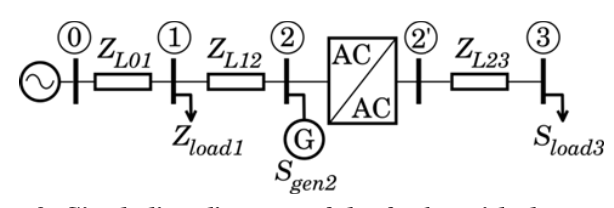

% 清理工作区和命令窗口
clear;
clc;

% Node voltages
V0 = 1.02; % Voltage at Node 0 [pu]

% Line impedances
ZL01 = 0.01; % Impedance between Node 0 and Node 1 [pu]
ZL12 = 0.03 + 1i * 0.01; % Impedance between Node 1 and Node 2 [pu]
ZL23 = 0.05 + 1i * 0.01; % Impedance between Node 2 and Node 3 [pu]

% Load and generation
Sload3 = 0.8 - 1i * 0.01; % Load at Node 3 [pu]
Yload1 = 0.1 - 1i * 0.03; % Load admittance at Node 1

% Extract real and imaginary components of Node 3's load power
Pload3 = real(Sload3); % Active power
Qload3 = imag(Sload3); % Reactive power

### `Calculate admittances/Define admittance matrices`

% Calculate admittances from impedances
YL01 = 1 / ZL01; % Admittance between Node 0 and Node 1
YL12 = 1 / ZL12; % Admittance between Node 1 and Node 2
YL23 = 1 / ZL23; % Admittance between Node 2 and Node 3

% Admittance matrix for the section between Node 0 and Node 2
Y1 = [YL01, -YL01, 0;
     -YL01, YL01 + YL12 + Yload1, -YL12;
      0, -YL12, YL12];

% Extract elements from the admittance matrix (real and imaginary parts)
G01 = real(Y1(1,2)); B01 = imag(Y1(1,2)); % Node 0 to Node 1
G11 = real(Y1(2,2)); B11 = imag(Y1(2,2)); % Node 1
G12 = real(Y1(2,3)); B12 = imag(Y1(2,3)); % Node 1 to Node 2
G22 = real(Y1(3,3)); B22 = imag(Y1(3,3)); % Node 2

% Admittance matrix for the section between Node 2 and Node 3
Y2 = [YL23, -YL23;
     -YL23, YL23];

% Extract elements from the admittance matrix (real and imaginary parts)
G22_prime = real(Y2(1,1)); B22_prime = imag(Y2(1,1)); % Node 2'
G23 = real(Y2(1,2)); B23 = imag(Y2(1,2)); % Node 2' to Node 3
G33 = real(Y2(2,2)); B33 = imag(Y2(2,2)); % Node 3

### `Iterate over the voltage range of Node 3`

% Initialize variables to track the minimum V2_prime
min_V2_prime = Inf; % Start with infinity
best_x = []; % To store the solution corresponding to min_V2_prime
best_V3 = []; % To store the corresponding V3

% Loop over the voltage range of Node 3 (0.96 to 1.04)
for V3 = 0.96:0.01:1.04
    % Define the power balance equations
    f = @(x) [
        % Active power balance at Node 1
        V0*x(1)*(G01*cos(x(4)) + B01*sin(x(4))) + x(1)^2*G11 + x(1)*x(2)*(G12*cos(x(4) - x(5)) + B12*sin(x(4) - x(5)));
        % Active power balance at Node 2
        x(1)*x(2)*(G12*cos(x(5) - x(4)) + B12*sin(x(5) - x(4))) + x(2)^2*G22 + x(8);
        % Active power balance at Node 2'
        x(3)*V3*(G23*cos(x(6) - x(7)) + B23*sin(x(6) - x(7))) + x(3)^2*G22_prime - x(8);
        % Active power balance at Node 3
        x(3)*V3*(G23*cos(x(7) - x(6)) + B23*sin(x(7) - x(6))) + V3^2*G33 + Pload3;
        % Reactive power balance at Node 1
        V0*x(1)*(G01*sin(x(4)) - B01*cos(x(4))) - x(1)^2*B11 + x(1)*x(2)*(G12*sin(x(4) - x(5)) - B12*cos(x(4) - x(5)));
        % Reactive power balance at Node 2
        x(1)*x(2)*(G12*sin(x(5) - x(4)) - B12*cos(x(5) - x(4))) - x(2)^2*B22;
        % Reactive power balance at Node 2'
        -x(3)^2*B22_prime + x(3)*V3*(G23*sin(x(6) - x(7)) - B23*cos(x(6) - x(7))) - x(9);
        % Reactive power balance at Node 3
        x(3)*V3*(G23*sin(x(7) - x(6)) - B23*cos(x(7) - x(6))) - V3^2*B33 + Qload3
    ];

    % Initial guess for the variables
    x0 = [1.02; 1.02; 1.02; 0; 0; 0; 0; 0; 0];

    % Solve the nonlinear equations using fsolve
    options = optimoptions('fsolve', 'Display', 'off');
    [x, ~, exitflag] = fsolve(f, x0, options);

    % Check if the solution is valid
    if exitflag > 0 % Solution found
        V2_prime = x(3); % Extract V2_prime
        if V2_prime < min_V2_prime
            % Update the minimum V2_prime
            min_V2_prime = V2_prime;
            best_x = x; % Store the solution
            best_V3 = V3; % Store the corresponding V3
        end
    else
        fprintf('Solver failed for V3 = %.2f\n', V3);
    end
end

### `Display results`

fprintf('Minimum V2_prime: %.4f\n', min_V2_prime);

Minimum V2_prime: 1.0016


fprintf('Corresponding V3: %.2f\n', best_V3);

Corresponding V3: 0.96


fprintf('Optimal variables:\n');

Optimal variables:


fprintf('V1 = %.4f\n', best_x(1));

V1 = 1.0105


fprintf('V2 = %.4f\n', best_x(2));

V2 = 0.9851


fprintf('V2_prime = %.4f\n', best_x(3));

V2_prime = 1.0016


fprintf('theta1 = %.4f rad\n', best_x(4));

theta1 = 0.0004 rad


fprintf('theta2 = %.4f rad\n', best_x(5));

theta2 = -0.0080 rad


fprintf('theta2_p = %.4f rad\n', best_x(6));

theta2_p = 0.0044 rad


fprintf('theta3 = %.4f rad\n', best_x(7));

theta3 = -0.0044 rad


fprintf('P = %.4f\n', best_x(8));

P = 0.8347


fprintf('Q = %.4f\n', best_x(9));

Q = -0.0031


## Task3:

The steps are quite the same as the $\textrm{Task}\;1$ and $\textrm{Task}\;2$

% Clear the workspace and command window
clear;
clc;

% System parameters
V0 = 1.02; % Slack node voltage [pu]
V3_fixed = 1.0; % Fixed voltage at Node 3 [pu]
ZL01 = 0.01; % Impedance from node 0 to node 1 [pu]
ZL12 = 0.03 + 1i * 0.01; % Impedance from node 1 to node 2 [pu]
ZL23 = 0.05 + 1i * 0.01; % Impedance from node 2 to node 3 [pu]
Sload3 = 0.8 - 1i * 0.01; % Load at node 3 [pu]

% Admittance calculations
YL01 = 1 / ZL01; % Admittance from node 0 to node 1
YL12 = 1 / ZL12; % Admittance from node 1 to node 2
YL23 = 1 / ZL23; % Admittance from node 2 to node 3
Yload1 = 0.1 - 1i * 0.03; % Load admittance at node 1
Pload3 = real(Sload3); % Active power at node 3
Qload3 = imag(Sload3); % Reactive power at node 3

% Extract G and B matrix elements for admittance matrix formulation
% Node 0 to Node 2
Y1 = [YL01, -YL01, 0;
      -YL01, YL01 + YL12 + Yload1, -YL12;
       0, -YL12, YL12];
G01 = real(Y1(1, 2)); B01 = imag(Y1(1, 2));
G11 = real(Y1(2, 2)); B11 = imag(Y1(2, 2));
G12 = real(Y1(2, 3)); B12 = imag(Y1(2, 3));
G22 = real(Y1(3, 3)); B22 = imag(Y1(3, 3));

% Node 2 to Node 3
Y2 = [YL23, -YL23;
      -YL23, YL23];
G22_prime = real(Y2(1, 1)); B22_prime = imag(Y2(1, 1));
G23 = real(Y2(1, 2)); B23 = imag(Y2(1, 2));
G33 = real(Y2(2, 2)); B33 = imag(Y2(2, 2));


### `Initialize arrays to store results`

% Initialize analysis for reactive power range
Q_MFC_values = 0.0:0.05:0.5; % Reactive power values [pu]
V2_results = zeros(size(Q_MFC_values)); % To store V2 results
Loss_results = zeros(size(Q_MFC_values)); % To store line loss results

### `Iterate over the range of Q_MFC values`

`The power balance equations are quite the same as the `$\textrm{Task2}$

% Loop through each Q_MFC value
for idx = 1:length(Q_MFC_values)
    Q_MFC = Q_MFC_values(idx);

    % Define the power balance equations
    f = @(V1, V2, V2_prime, theta1, theta2, theta2_p, theta3, P, Q) [
        % Active power balance at Node 1
        V0 * V1 * (G01 * cos(theta1) + B01 * sin(theta1)) + V1^2 * G11 + V1 * V2 * (G12 * cos(theta1 - theta2) + B12 * sin(theta1 - theta2));
        % Active power balance at Node 2
        V1 * V2 * (G12 * cos(theta2 - theta1) + B12 * sin(theta2 - theta1)) + V2^2 * G22 + P;
        % Active power balance at Node 2'
        V2_prime * V3_fixed * (G23 * cos(theta2_p - theta3) + B23 * sin(theta2_p - theta3)) + V2_prime^2 * G22_prime - P;
        % Active power balance at Node 3
        V2_prime * V3_fixed * (G23 * cos(theta3 - theta2_p) + B23 * sin(theta3 - theta2_p)) + V3_fixed^2 * G33 - Pload3;
        % Reactive power balance at Node 1
        V0 * V1 * (G01 * sin(theta1) - B01 * cos(theta1)) - V1^2 * B11 + V1 * V2 * (G12 * sin(theta1 - theta2) - B12 * cos(theta1 - theta2));
        % Reactive power balance at Node 2
        V1 * V2 * (G12 * sin(theta2 - theta1) - B12 * cos(theta2 - theta1)) - V2^2 * B22 - Q_MFC;
        % Reactive power balance at Node 2'
        -V2_prime^2 * B22_prime + V2_prime * V3_fixed * (G23 * sin(theta2_p - theta3) - B23 * cos(theta2_p - theta3)) - Q;
        % Reactive power balance at Node 3
        V2_prime * V3_fixed * (G23 * sin(theta3 - theta2_p) - B23 * cos(theta3 - theta2_p)) - V3_fixed^2 * B33 + Qload3
    ];

    % Solve power balance equations
    fp = @(x) f(x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8), x(9));
    x0 = [1.02; 1.02; 1.02; 0; 0; 0; 0; 0; 0]; % Initial guess
    options = optimoptions('fsolve', 'Display', 'off');
    [x, ~, exitflag] = fsolve(fp, x0, options);

    if exitflag > 0
        % Store results
        V2_results(idx) = x(2); % Voltage at Node 2
        % Calculate line losses
        Loss_results(idx) = abs(V0 - x(1))^2 * real(YL01) + ...
                            abs(x(1) - x(2))^2 * real(YL12) + ...
                            abs(x(3) - V3_fixed)^2 * real(YL23);
    else
        % Assign NaN for invalid results
        V2_results(idx) = NaN;
        Loss_results(idx) = NaN;
    end
end

`Convert the equations into a single-variable function for fsolve and provide variables`

`Check if the solver converged successfully`

### `Display the results`

% Plot results
figure;
subplot(2, 1, 1);
plot(Q_MFC_values, V2_results, 'o-');
xlabel('Q_{MFC} [pu]');
ylabel('V2 [pu]');
title('Node 2 Voltage vs Q_{MFC}');
grid on;

### `Plot the voltage at Node 3 against Q_MFC`

% Display results
fprintf('Q_MFC Analysis:\n');

Q_MFC Analysis:


for idx = 1:length(Q_MFC_values)
    fprintf('Q_MFC = %.2f pu -> V2 = %.4f pu, Loss = %.4f pu\n', ...
            Q_MFC_values(idx), V2_results(idx), Loss_results(idx));
end

Q_MFC = 0.00 pu -> V2 = 1.0483 pu, Loss = 0.0493 pu
Q_MFC = 0.05 pu -> V2 = 1.0487 pu, Loss = 0.0499 pu
Q_MFC = 0.10 pu -> V2 = 1.0492 pu, Loss = 0.0506 pu
Q_MFC = 0.15 pu -> V2 = 1.0497 pu, Loss = 0.0512 pu
Q_MFC = 0.20 pu -> V2 = 1.0501 pu, Loss = 0.0519 pu
Q_MFC = 0.25 pu -> V2 = 1.0506 pu, Loss = 0.0526 pu
Q_MFC = 0.30 pu -> V2 = 1.0510 pu, Loss = 0.0532 pu
Q_MFC = 0.35 pu -> V2 = 1.0515 pu, Loss = 0.0539 pu
Q_MFC = 0.40 pu -> V2 = 1.0519 pu, Loss = 0.0546 pu
Q_MFC = 0.45 pu -> V2 = 1.0524 pu, Loss = 0.0553 pu
Q_MFC = 0.50 pu -> V2 = 1.0528 pu, Loss = 0.0560 pu


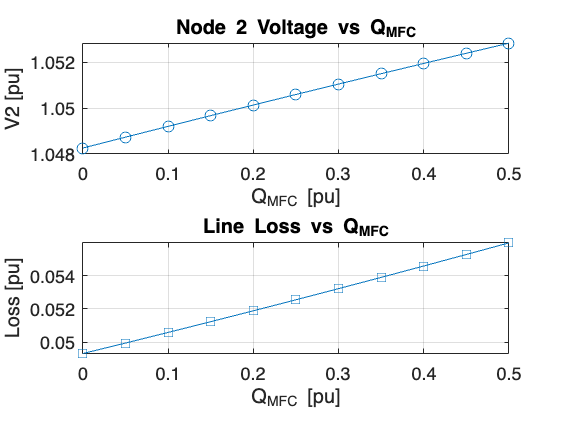



subplot(2, 1, 2);
plot(Q_MFC_values, Loss_results, 's-');
xlabel('Q_{MFC} [pu]');
ylabel('Loss [pu]');
title('Line Loss vs Q_{MFC}');
grid on;

Therefore, according to the graph as shown, the provision of reactive pwoer to node (2) by the MFC will not improve the operation of the feeder